clc,clear;
SFC = SignalFlowChart();
SFC.createSFC('Miller_OTA.txt')
[details, TF, dcGain, poles, zeros] = SFC.solveTF;
[newTF, p, z, DCgain] = SFC.simplifyTF(TF)

$$newTF = -\frac{{\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,\left(\frac{\mathrm{Cc}\,s}{{\mathrm{gm}}_{2}}-1\right)}{\left(\frac{s\,\left(C_{1}\,\mathrm{CL}+C_{1}\,\mathrm{Cc}+\mathrm{CL}\,\mathrm{Cc}\right)}{\mathrm{Cc}\,{\mathrm{gm}}_{2}}+1\right)\,\left(\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}\,s+1\right)}$$

$$p = \left(\begin{array}{cc} -\frac{\mathrm{Cc}\,{\mathrm{gm}}_{2}}{C_{1}\,\mathrm{CL}+C_{1}\,\mathrm{Cc}+\mathrm{CL}\,\mathrm{Cc}} & -\frac{1}{\mathrm{Cc}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}} \end{array}\right)$$

$$z = \frac{{\mathrm{gm}}_{2}}{\mathrm{Cc}}$$

$$DCgain = {\mathrm{gm}}_{1}\,{\mathrm{gm}}_{2}\,{\mathrm{ro}}_{1}\,{\mathrm{ro}}_{2}$$

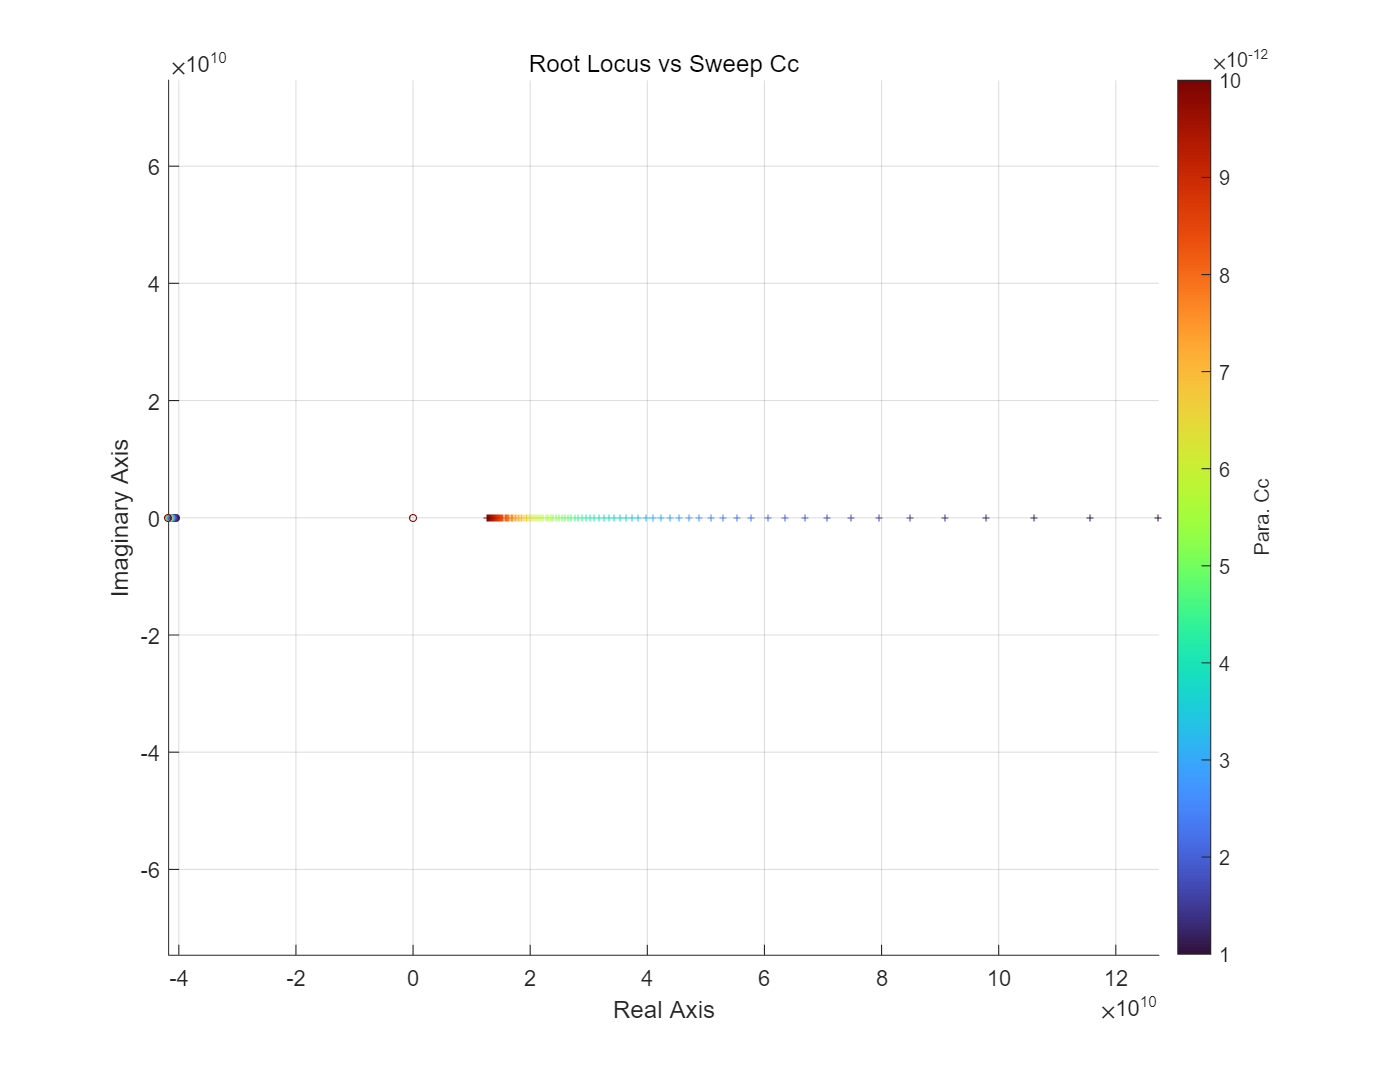

r = 包含以下字段的 struct :
     poles: [-1    -1]
     zeros: 4/(5*Cc)
    DCgain: 4400000


SFC.SFParser.registerValue('Miller_OTA.txt')
r = SFC.analysisTF(TF, 'RLocus', 1e-12:1e-13:10e-12)